**Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, **

**Melani Tatayo Culchas, Rubén Sierra Serrano**

Fecha: 16/04/2023

# **Ejercicio 1**

## T5.1. Polinomio de ajuste

clear, clc % Limpieza del entorno de trabajo

a)  Crea una función de Matlab que calcule el polinomio de ajuste por mínimos cuadrados para un conjunto de datos.

- Véase PoliMulti.m

b) Emplea la función del apartado a) para resolver la siguiente cuestión:

 Dados los siguientes datos obtenidos en un experimento:

 

x = [-.04, .93, 1.95, 2.90, 3.83, 5, 5.98, 7.05, 8.21, 9.08, 10.09];
y = [-8.66, -6.44, -4.36, -3.27, -0.88, 0.87, 3.31, 4.63, 6.19, 7.40, 8.85];

Determina el grado del polinomio que mejor se ajusta a los datos (desviación estándar menor).

n = numel(x);
desv_std = zeros(1, n-1);
for i = 1: n-1
    [~, ~, s] = PoliMulti(x, y, i);
    desv_std(i) = s;
end

Mostramos en una tabla los resultados:

grado = 1: n-1;
tabla_desviaciones = table( ...
    grado', num2str(desv_std', '%.4f'), ...
    VariableNames={'Grado', 'Desviación estándar'});
disp(tabla_desviaciones)

    Grado    Desviación estándar
    _____    ___________________

      1            0.2179       
      2            0.0852       
      3            0.2274       
      4            0.2534       
      5            0.2574       
      6            0.3286       
      7            0.3699       
      8            0.4531       
      9            0.6190       
     10               Inf       



Usando la función min de MATLAB podemos encontrar el grado de menor desviación estándar:

[min_desv, i] = min(desv_std);
fprintf("El grado del polinomio que mejor ajusta es:\n%d", i)

El grado del polinomio que mejor ajusta es:
2

fprintf("Presentando una desviación estándar de:\n%f", min_desv)

Presentando una desviación estándar de:
0.085167

Representa gráficamente el polinomio y los puntos de datos y calcula el error total

Hemos obtenido que el grado del polinomio que mejor ajusta es 2 (i = 2).

[p, error_total, ~] = PoliMulti(x, y, i);

Dibujamos los resultados obtenidos junto a los datos:

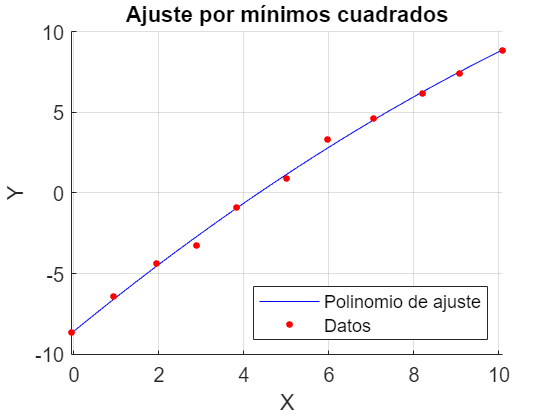

% Límites del dibujo
l1 = min(x); l2 = max(x);
t = linspace(l1,l2);
% Dibujo
hold on
plot(t, polyval(p, t),"-b"); % Polinomio de ajuste
plot(x, y, 'r.', MarkerSize=10) % Datos iniciales

title('Ajuste por mínimos cuadrados')
xlabel('X'); ylabel('Y');
xlim([l1, l2]);
grid
legend('Polinomio de ajuste', 'Datos', 'Location','southeast')
hold off

La función Polimulti() nos ha devuelto también el error total:

fprintf("El error total es:\n%f", error_total)

El error total es:
0.058027

# **Ejercicio 2**

## T5.2 Método de interpolacion de Neville

Limpieza del entorno de trabajo

clear, clc      % Limpieza del entorno de trabajo

a) Escribe una función de Matlab que calcule el punto de interpolación mediante el método de Neville.

- Véase Neville.m

b) Emplea la función del apartado a) para encontrar la raíz 𝑦(𝑥) = 0. Comprueba el

resultado con las raíces del polinomio de interpolación de segundo grado 

calculado con la función polyfit de Matlab.Representa los puntos y 

la función de interpolación con el fin de verificar la posición 

de la raíz encontrada.

Datos de la tabla:

x = [4.0; 3.9; 3.8; 3.7];
y = [-0.06604; -0.02724; 0.01282; 0.05383];

Se acomodan los vectores para poder representar gráficamente el polinomio de interpolación, además de buscar la raíz de `y(x)=0`

% Límites del dibujo
l1 = min(x); l2 = max(x);
xx = linspace(l1,l2)';
n = length(xx);
yy = zeros(1, n)';
for i=1:length(xx)
    yy(i) = Neville(x,y,xx(i));
end

Se encuentra la raíz

indice = find(abs(yy) == min(abs(yy)));

Se imprime la aproximación de la raíz

fprintf('Raíz obtenida por Neville: x = %.4f\n', xx(indice))

Raíz obtenida por Neville: x = 3.8303


Calculamos las raíces del polinomio de interpolación de segundo grado con `polyfit`

p = polyfit(x, y, 2);
raices = roots(p);

 Se imprime las raíces del polinomio de interpolación

fprintf('Raíces del polinomio de interpolación:\nx = %.4f, x = %.4f', raices(1), raices(2))

Raíces del polinomio de interpolación:
x = 11.1022, x = 3.8317

Tomamos la segunda raíz que es la que coincide con nuestra interpolación

r = raices(2)

Se representan los puntos y la función de interpolación

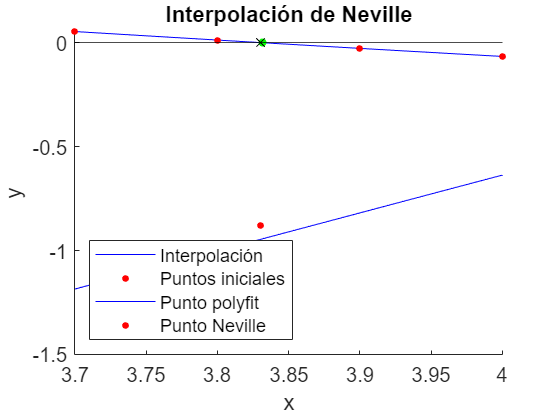

hold on
plot(xx, yy, "b-");
plot(x,y,"r.", MarkerSize=10);
plot(r, 0, "g.", MarkerSize=12);
plot(xx(indice), yy(indice), "kx");
yline(0, 'k');

title('Interpolación de Neville');
xlabel("x"); ylabel("y");
xlim([l1, l2]);
grid
legend("Interpolación","Puntos iniciales", "Punto polyfit", "Punto Neville",Location="southwest");
hold off

# **Ejercicio 3**

## T5.3 Polinomio de interpolación de Lagrange

a) Desarrollar una función en Matlab que interpole un conjunto de puntos utilizando un polinomio de Lagrange. La función debe tener la forma:

`Yint=LagINT(x,y,Xint)`

La entrada de la función son las coordenadas de los puntos de datos dados (`x,y`) y la coordenada `Xint `en el punto en el que se debe calcular el valor interpolado de y. La salida de la función es el valor interpolado de y, `Yint.`

- `Véase LagINT.m  `

b) Se da el conjunto de los siguientes cinco puntos de datos:

Emplear la función creada para representar gráficamente el polinomio de interpolación y los puntos dados. Calcular el valor interpolado en $x=3$

Preparamos el entorno de trabajo

clear
clc
close all

Zona de declaración de variables

x = [1 2 4 5 7];
y = [52 5 -5 -40 10];
Xint = 3;

Llamamos a la función y mostramos el resultado

Yint = LagINT(x,y,Xint);
fprintf("El punto de interpolación obtenido en x = 3 toma el valor: %.3f",Yint)

El punto de interpolación obtenido en x = 3 toma el valor: 6.000

Acomodamos los vectores para poder representar gráficamente el polinomio de interpolación 

% Límites del dibujo
l1 = min(x); l2 = max(x);
xx = linspace(l1,l2);
n = length(xx);
yy = zeros(1, n);
for i=1:n
    yy(i) = LagINT(x,y,xx(i));
end

Representación gráfica

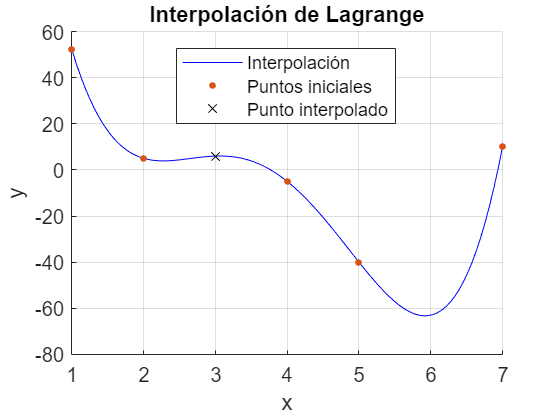

hold on
plot(xx,yy,"b-");
plot(x, y, '.', MarkerSize=10);
plot(Xint,Yint,"kx");

title("Interpolación de Lagrange");
xlabel("x"); ylabel("y");
xlim([l1, l2])
grid
legend("Interpolación","Puntos iniciales","Punto interpolado","Location","best");
hold off

# **Ejercicio 4**

## T5.4 Polinomio de interpolación de Newton

a) Escribe una función de MATLAB que interpole unos puntos dados utilizando el polinomio de Newton. Nómbrala:

`Yint` `=` `NewtonINT(x,y,Xint)`

La entrada de la función deben ser las coordenadas de los puntos de datos dados en dos vectores `x` e `y` y la coordenada `Xint` del punto en el que se va a interpolar. La salida de la función es el valor `Yint` del punto interpolado. Sugerencia: Inicia el programa calculando las primeras diferencias divididas, que luego se utilizan para calcular las diferencias divididas superiores. Asigna los valores a una matriz. Los coeficientes del polinomio (primera fila de la matriz) se asignan entonces a un vector.

b) Dado el siguiente conjunto de puntos:

Emplea la función creada anteriormente para obtener el valor para $x=3$. Representa gráficamente el polinomio y los puntos interpolados

Preparamos el entorno de trabajo

clear
clc
close all

Zona de declaración de variables

x = [0 1 2 5.5 11 13 16 18];
y = [0.5 3.134 5.3 9.9 10.2 9.35 7.2 6.2];
Xint = 3;

Llamamos a la función y mostramos el resultado

Yint = NewtonINT(x,y,Xint);
fprintf("El punto de interpolación obtenido en x = 3 toma el valor: %.3f",Yint)

El punto de interpolación obtenido en x = 3 toma el valor: 7.072

Acomodamos los vectores para poder representar gráficamente el polinomio de interpolación 

% Límites del dibujo
l1 = min(x); l2 = max(x);
xx = linspace(l1, l2);
n = length(xx)

n = 100

yy = zeros(1, n);
for i=1:n
    yy(i) = NewtonINT(x,y,xx(i));
end

Representación gráfica

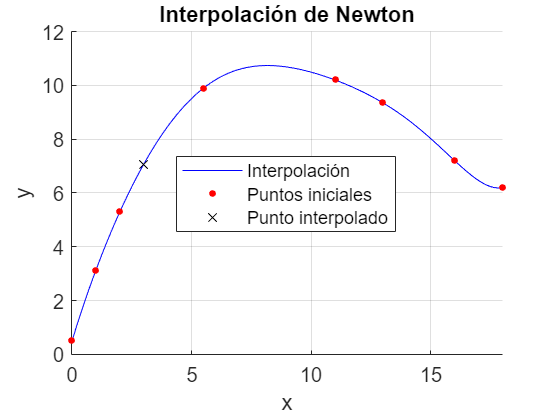

hold on
plot(xx,yy,"b-");
plot(x,y,"r.", MarkerSize=10)
plot(Xint,Yint,"kx")

title("Interpolación de Newton");
xlabel("x"); ylabel("y");
xlim([l1, l2])
grid
legend("Interpolación","Puntos iniciales","Punto interpolado","Location","best");
hold off

# **Ejercicio 5**

## Problema T5.5. **Interpolación mediante spline cúbicas con polinomios de  Lagrange**

a) Escribe una función de MATLAB para la interpolación con splines  cúbicas naturales mediante polinomios de Lagrange de tercer grado.

- Véase SplineCub.m adjunta.

b) Los valores de la entalpía por unidad de masa, h, de un plasma de  argón en equilibrio (Ar, Ar+, A++, A+++ iones y electrones) frente a la  temperatura son:

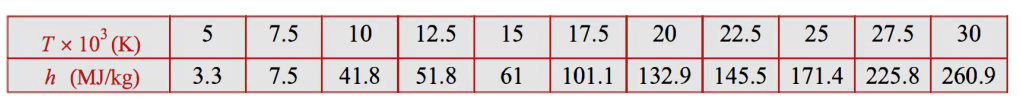

T = [5, 7.5, 10, 12.5, 15, 17.5, 20, 22.5, 25, 27.5, 30]; % T x 10^3 K
h = [3.3, 7.5, 41.8, 51.8, 61, 101.1, 132.9, 145.5, 171.4, 225.8, 260.9];% h (Mg/kg)

*Nota: Las unidades de la Temperatura (T) son Kelvin y las unidadesde la entalpía por unidad de masa (h) son MJ/kg.*

Escribe un programa en un archivo de script que utilice la interpolación mediante la función SplineCub para generar una gráfica que muestre las curvas  de interpolación (splines), y los puntos de datos de la tabla (utiliza círculos rojos  para los puntos).

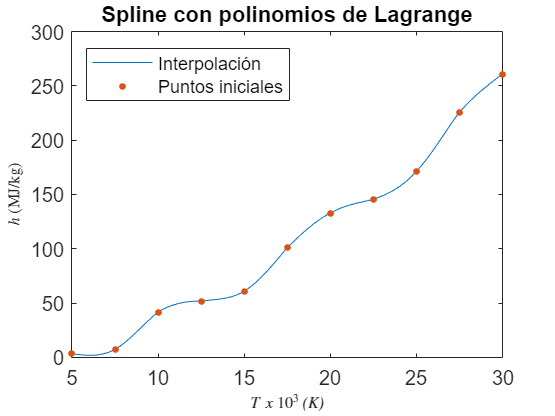

dibujo_spline
hold off

Calcula la entalpía por unidad de masa a T = 14000 ºK y T = 24000 ºK.

T1 = 14;
T2 = 24;
h1 = SplineCub(T, h, T1);
fprintf("Entalpía h1 = %.2f Mg/kg",h1)

Entalpía h1 = 54.90 Mg/kg

h2 = SplineCub(T, h, T2);
fprintf("Entalpía h2 = %.2f Mg/kg",h2)

Entalpía h2 = 157.19 Mg/kg

Se representan los puntos calculados mediante la función spline con círculos azules.

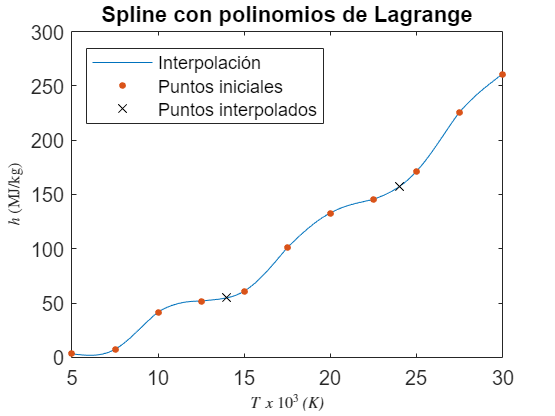

dibujo_spline
plot([T1, T2], [h1, h2], 'kx');
legend("Interpolación","Puntos iniciales", "Puntos interpolados","Location","northwest");
hold off